# Machine Learning with MATLAB 

Digital Twin & Automation

# Logistic Regression

## Binary linear classifier

`Method 1:`fitclinear()

- For two-class (binary) learning with **high-dimensional**, full or sparse predictor data. 

`Method 2:`fitglm()

- For low- through medium-dimensional predictor data sets, see [Alternatives for Lower-Dimensional Data](https://www.mathworks.com/help/releases/R2021b/stats/fitclinear.html#mw_d1b0a02e-0dfa-4c0e-bb4d-e6859309ec45)

## **Example 1: Logistic Regression**

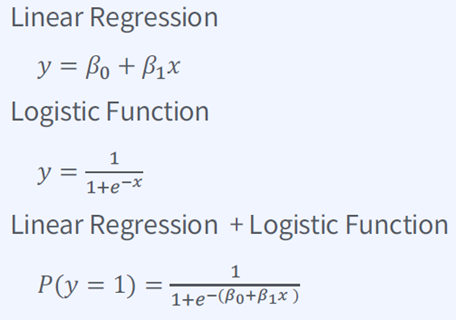

**Data Acquisition** 

clear 

load fisheriris

% binary로 하기 때문에, 2개의 feature만 본다
% setosa (꽃의 종류)라는 class만 본다 : setosa 꽃 인지 or 아닌지
X = meas(:,1:2);                    % Use two features (x1, x2) for fitting
sp = categorical(species);
Ystat = sp == 'setosa';             % Binary classfication:  setosa vs no-setosa

**Classification: **Logistic Regression 

% fitclinear : 일반화된 선형 회귀 모델을 피팅
Mdl = fitclinear(X,Ystat,'Learner','logistic')

Mdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'logit'
              Beta: [2×1 double]
              Bias: 8.3233
            Lambda: 0.0067
           Learner: 'logistic'


  Properties, Methods


**Plot**  Logistic Regression of Train data:  z vs Logistic Function

- z = w0 + w1X1 + w2X2

- y = 1 / (1+exp(-z))

% Plot z vs Y = sigmoid(z)
% fitclinear를 하게되면 그 안에Beta값이 모두 들어있다.
% Beta 1,2 : w1, w2

% z = Wx + b form
z = Mdl.Bias + X * Mdl.Beta;

Y = 1./ (1 + exp(-z));  % Logistic function

Y1indx = find(sp == 'setosa')

Y1indx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Y0indx = find(sp~='setosa')

Y0indx =     51
    52
    53
    54
    55
    56
    57
    58
    59
    60


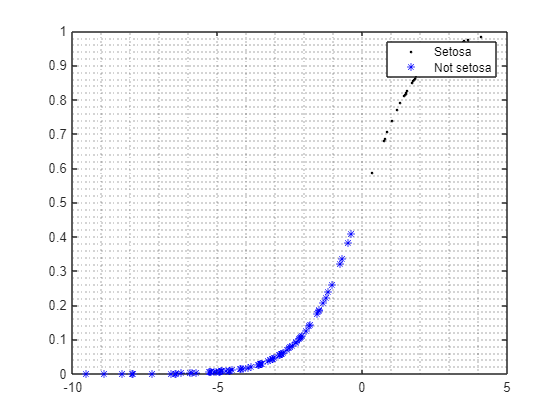

figure
plot(z(Y1indx),Y(Y1indx),'k.', LineWidth = 2) 
hold on 
plot(z(Y0indx),Y(Y0indx),'b*') 
hold off;   legend('Setosa','Not setosa');  grid minor;     

#### Cross-validation (k-fold)

Construct a cross-validated classifier from the model.

cvMdl = fitclinear(X,Ystat,'Learner','logistic', 'KFold',5)

cvMdl =   ClassificationPartitionedLinear
    CrossValidatedModel: 'Linear'
           ResponseName: 'Y'
        NumObservations: 150
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


Examine the cross-validation loss, which is the average loss of each cross-validation model when predicting on data that is not used for training.

kloss = kfoldLoss(cvMdl)

kloss = 0

**Test **  

% an average flower feature values
flwr = mean(X); 
flwr2 = mean(X(1:10,:)); 
Xtest=flwr2;

% Convert TestData as Logistic Function
ztest=Mdl.Bias+Xtest*Mdl.Beta;

Ytest= 1./(1+exp(-ztest))

Ytest = 0.9114

flwrClass = predict(Mdl,Xtest)

flwrClass = logical
   1


# Exercise

## Exercise 1:  CWRU dataset

Apply logistic regression to classifiy   outer or  inner bearing fault  

### Dataset 

- Given dataset contains many features extracted from CWRU dataset

- For binary class:  Outer and Inner Race Fault

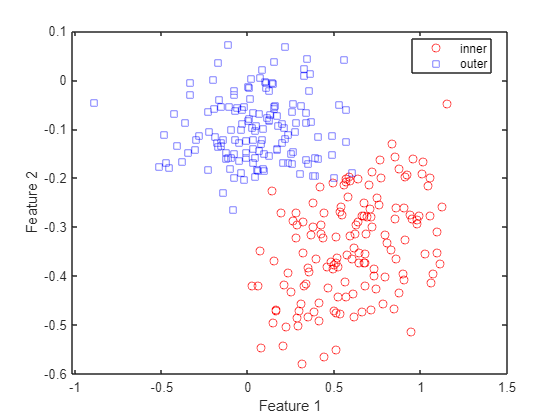

clear

% Class 'Inner', 'Outer'
load("../3_MachingLearning/CWRU_Datas/example_train.mat");

% 2개의 feature를 설정
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor

% 두 개의 class : sv, ipf에 대한 Xtrain table을 생성
Xtrain(:, 1) = table2array(glob_all_train(:, feature1));
Xtrain(:, 2) = table2array(glob_all_train(:, feature2));

Ytrain = class_cwru_train;                 % fault class
classKeep = ~strcmp(Ytrain,'normal');       % eliminate normal class

% X : SV value , IF value of fault data
X = Xtrain(classKeep,:);  
% Y : Inner or Outer
Y = Ytrain(classKeep);

% Plot features 
f = figure;
gscatter(X(:,1), X(:,2), Y,'rb','os');
xlabel('Feature 1');
ylabel('Feature 2');

- **In Sigmoid form **

% Plot features 
sp = categorical(Y);

% Model 생성
Mdl = fitclinear(X, Y,'Learner','logistic');

% Class : inner / outer
z = Mdl.Bias + X * Mdl.Beta;

% logistic regression
Y = 1./ (1 + exp(-z));  
Y1indx = find(sp == 'inner')

Y1indx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Y0indx = find(sp ~= 'inner')

Y0indx =    145
   146
   147
   148
   149
   150
   151
   152
   153
   154


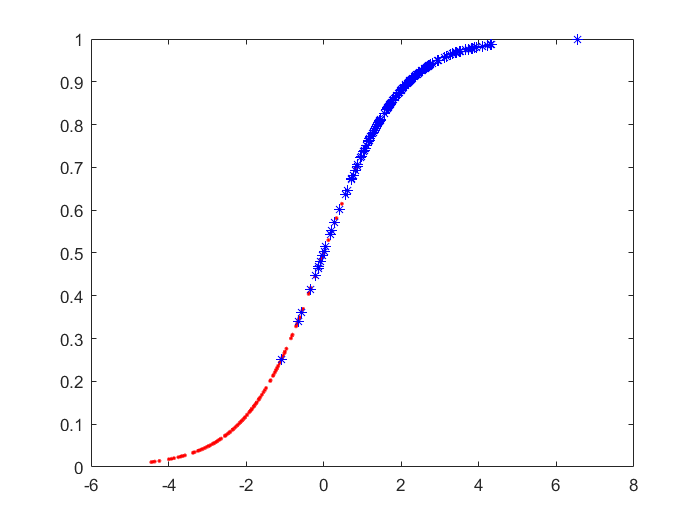

figure
plot(z(Y1indx),Y(Y1indx),'r.')
hold on
plot(z(Y0indx),Y(Y0indx),'b*')
hold off

**Classify using Logistic Regression and Analyze **

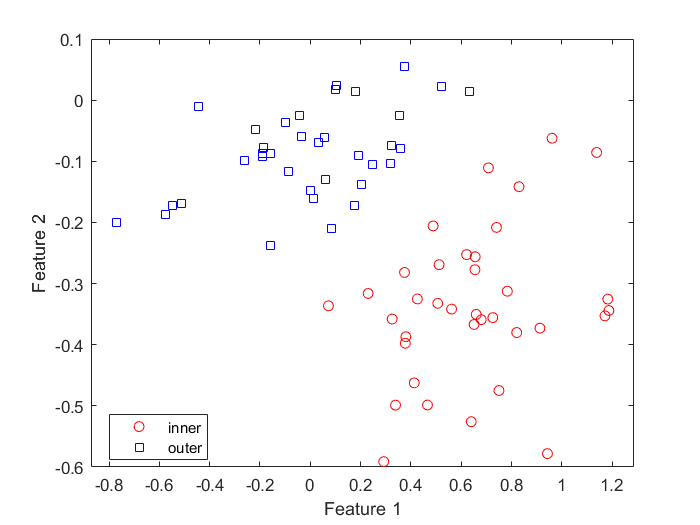

load("../3_MachingLearning/CWRU_Datas/example_test.mat");  

feature1 = "sv";
feature2 = "ipf";

Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Ytest = class_cwru_test;                                   % fault class

classKeepTest = ~strcmp(Ytest,'normal');                   % eliminate normal class

X_test = Xtest(classKeepTest,:);  
Y_test = Ytest(classKeepTest);

% Plot features 
f = figure;
gscatter(X_test(:,1), X_test(:,2), Y_test,'rb','os');
xlabel('Feature 1');
ylabel('Feature 2');

X_t = Xtest(classKeepTest,:);  
Y_t = Ytest(classKeepTest);                                      % Inner or Outer

spTest = categorical(Y_t);

Ypred = predict(Mdl, X_t);

**Predict  test data and Analyze**

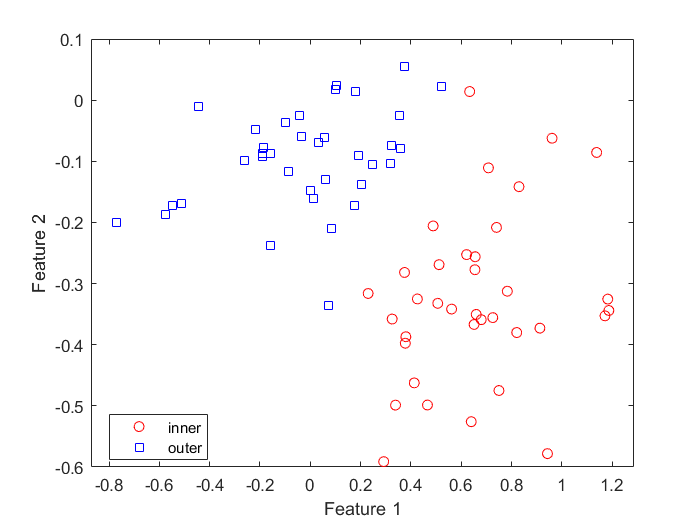

f = figure;
gscatter(X_t(:,1), X_t(:,2), Ypred,'rb','os');
xlabel('Feature 1');
ylabel('Feature 2');

## Exercise 2

- 과제

**Use gradient descent to obtain optimal parameters of Logistic Regression**

**Cost function**

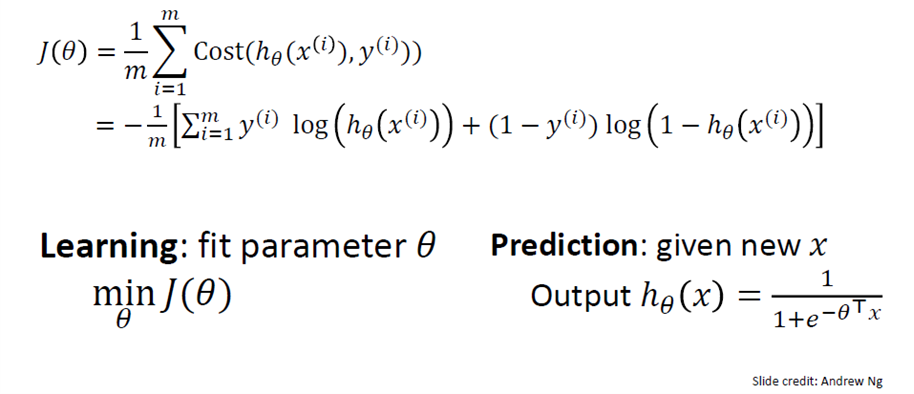

**Gradient Descent**

 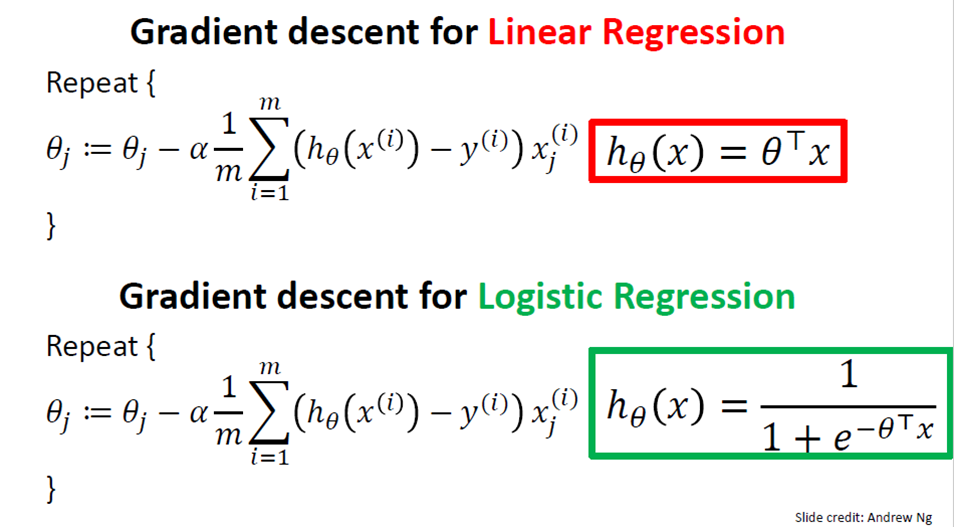

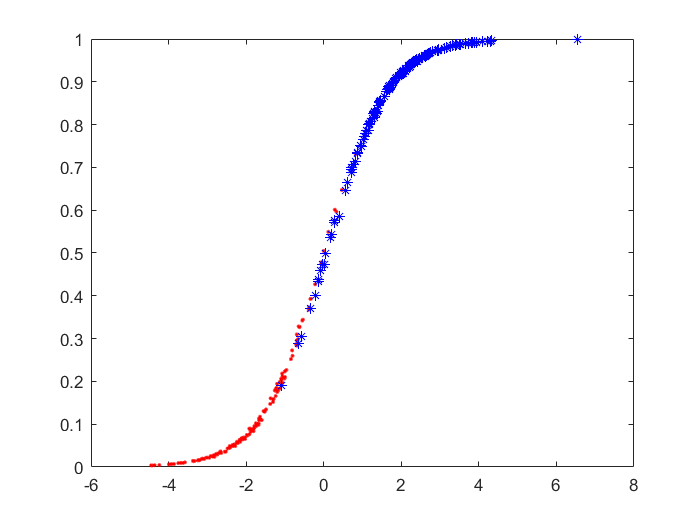

t0 = 0.5;   t1 = 0.5;   t2 = 0.5;
eta = 0.08;  e = 1;  itrN = 2000;    k=0;    

Y2num = zeros(length(Ytrain), 1);

exceptNorm = ~strcmp(Ytrain,'normal');
Ytrain = Ytrain(exceptNorm);

for IDX = 1 : length(Ytrain)

    Y2num(IDX, 1) = ~strcmp(Ytrain(IDX, 1), 'inner');

end


while(e > 0.001 || k < itrN)
    
    h = X * [t1 ; t2] + t0;
    H = 1./(1 + exp(-h));
    
    dJt2 = -(mean(X(:, 2) .* (Y2num - H)));
    dJt1 = -(mean(X(:, 1) .* (Y2num - H)));
    dJt0 = (-1) * mean(Y2num - H);
    
    t2_new = t2 - eta .* dJt2;
    t1_new = t1 - eta .* dJt1;
    t0_new = t0 - eta .* dJt0;

    e = 0.5 .* (abs((t2_new - t2)) + abs((t1_new - t1)) + abs((t0_new - t0)));
    
    t2 = t2_new;
    t1 = t1_new;
    t0 = t0_new;

    k = k+1;

end

figure
plot(z(Y1indx),H(Y1indx),'r.')
hold on
plot(z(Y0indx),H(Y0indx),'b*')
hold off

disp('Gradient descent result')

Gradient descent result


t2

t2 = 6.5529

t1

t1 = -5.8072

t0

t0 = 3.3108

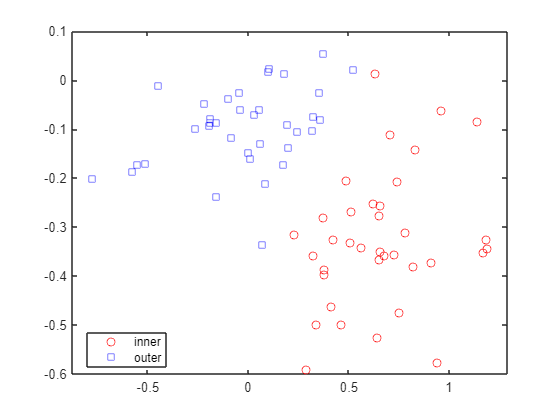

z_gradient = X_test * [t1; t2] + t0;
z_gradient = 1./(1 + exp(-z_gradient));

LEN = length(z_gradient);

Predict = cell(LEN,1);

for IDX = 1 : LEN

   if z_gradient(IDX,1) >= 0.5
    
       Predict{IDX} = 'outer'; 
   end

   if z_gradient(IDX,1) < 0.5
    
       Predict{IDX} = 'inner'; 
   end

end 

gscatter(X_t(:,1), X_t(:,2), Predict,'rb','os');